try different uniform and non-uniform data sets to get vital stats


clear variables;



dims = [4,8,16,32,64,128,256,512,1024];

meanEntropies = zeros(3,length(dims));
errors = zeros(3,length(dims));
errorStDev = zeros(3,length(dims));


for i = 1 : length(dims)
    dim = dims(i);
    disp(dim);

    [data,~,~,~] = get_data("Uniform",dim);
    rrots = getRandomRotations(dim,1,0);
    rrot = squeeze(rrots(1,:,:));
    data = data * rrot;

    entropyVals = zeros(3,1000);

    rabbitErrors = zeros(1,1000);
    evpErrors = zeros(1,1000);

    R = reshape(data(:,1:4),[4*size(data,1),1]);
    [~,C] = kmeans(R,4,"MaxIter",100);
    scalars = sort(C);

    for j = 1 : 1000
        rQuant = single(rabit2_mod(data(j,:)));
        entropyVals(1,j) = perplexity_fn(rQuant);

        rVec = rQuant - 1.5;
        rNormVec = rVec / norm(rVec);
        rabbitErrors(j) = data(j,:) * rNormVec';

        eQuant = getEVP_1_2(data(j,:));
        entropyVals(2,j) = perplexity_fn(eQuant);

        evpNormVec = eQuant / norm(eQuant);
        evpErrors(j) = data(j,:) * evpNormVec';

        tQuant = tq_quant(data(j,:)',scalars);
        entropyVals(3,j) = perplexity_fn(tQuant);
    end
    meanEntropies(:,i) = mean(entropyVals,2);

    errors(1,i) = mean(rabbitErrors);
    errorStDev(1,i) = std(rabbitErrors);

    errors(2,i) = mean(evpErrors);
    errorStDev(2,i) = std(evpErrors);
end

     4

     8

    16

    32

    64

   128

   256

   512

        1024



get the same info for some real data


datasets = ["GloVe","GloVe200","PubMed","Laion","Wiki"];

entsReal = zeros(3,length(datasets));
errorsReal = zeros(2,length(datasets));
errorStDevReal = zeros(2,length(datasets));

realdims = [];
for i = 1 : length(datasets)
    disp(datasets(i));
    [data,queries,gt,dataname] = get_data(datasets(i),-1);
    rrots = getRandomRotations(size(data,2),1);
    rrot = squeeze(rrots(1,:,:));
    data = data * rrot;
    queries = queries * rrot;
    disp(size(data,2));
    realdims = [realdims,size(data,2)];
    accRab = 0;
    rabbitErrors = zeros(1,1000);
    accEVP = 0;
    evpErrors = zeros(1,1000);
    accTQ = 0;

    R = reshape(data(:,1:4),[4*size(data,1),1]);
    [~,C] = kmeans(R,4,"MaxIter",100);
    scalars = sort(C);

    for j = 1 : 1000
        rQuant = rabit2(data(j,:));
        accRab = accRab + perplexity_fn(rQuant);

        rVec = rQuant - 1.5;
        rNormVec = rVec / norm(rVec);
        rabbitErrors(j) = data(j,:) * rNormVec';

        eQuant = getEVP_1_2(data(j,:));
        accEVP = accEVP + perplexity_fn(eQuant);

        evpNormVec = eQuant / norm(eQuant);
        evpErrors(j) = data(j,:) * evpNormVec';

        tVec = tq_quant(data(j,:)',scalars);
        accTQ = accTQ + perplexity_fn(tVec);
    end
    entsReal(1,i) = accRab / 1000;
    errorsReal(1,i) = mean(rabbitErrors);
    errorStDevReal(1,i) = std(rabbitErrors);

    entsReal(2,i) = accEVP / 1000;
    errorsReal(2,i) = mean(evpErrors);
    errorStDevReal(2,i) = std(evpErrors);

    entsReal(3,i) = accTQ / 1000;
end

GloVe


   100



GloVe200


   200



PubMed


   384



Laion


   768



Wiki


        1024




figure;
hold on;
ax=gca;
ax.FontSize=16;
xlim([0,1024]);
xlabel("dimension",FontSize=24)
ylabel("perplexity",FontSize=24)
title("Quantised vector perplexity with dimension",'Interpreter','latex',FontSize=32)
plot(dims,meanEntropies(3,:),LineWidth=2,LineStyle="--");
plot(dims,meanEntropies(1,:),LineWidth=2,LineStyle="-");
plot(dims,meanEntropies(2,:),LineWidth=2,Color="black",LineStyle="-.");
scatter(realdims,entsReal(3,:),70,"blue","filled");
scatter(realdims,entsReal(1,:),70,"red","filled");
scatter(realdims,entsReal(2,:),70,"black","filled");
legend("TurboQuant","RaBitQ","EVP","TurboQuant","RaBitQ","EVP",location="best",FontSize=16);

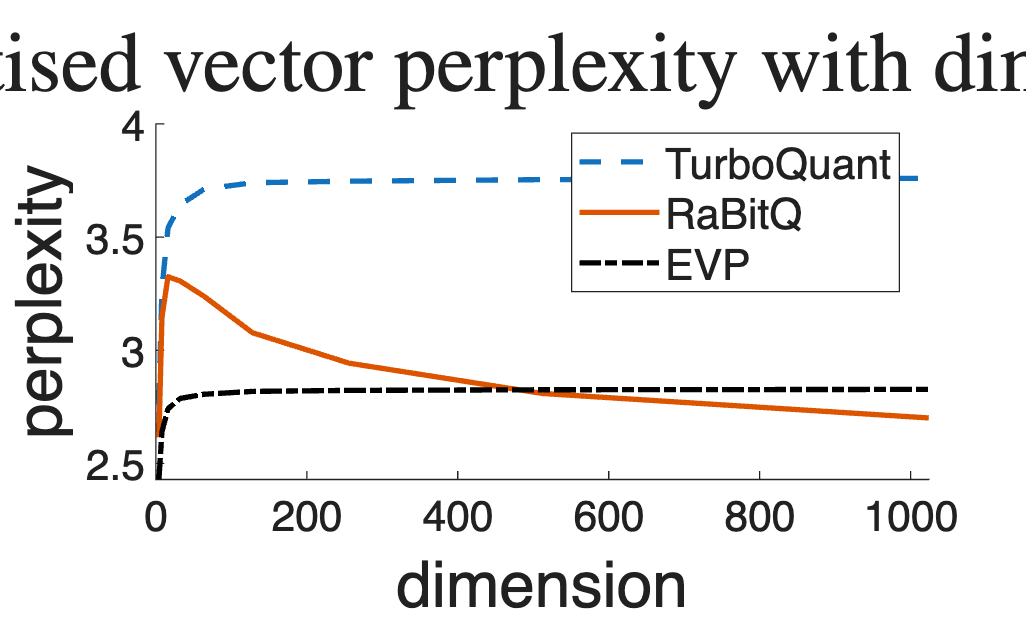

hold off;

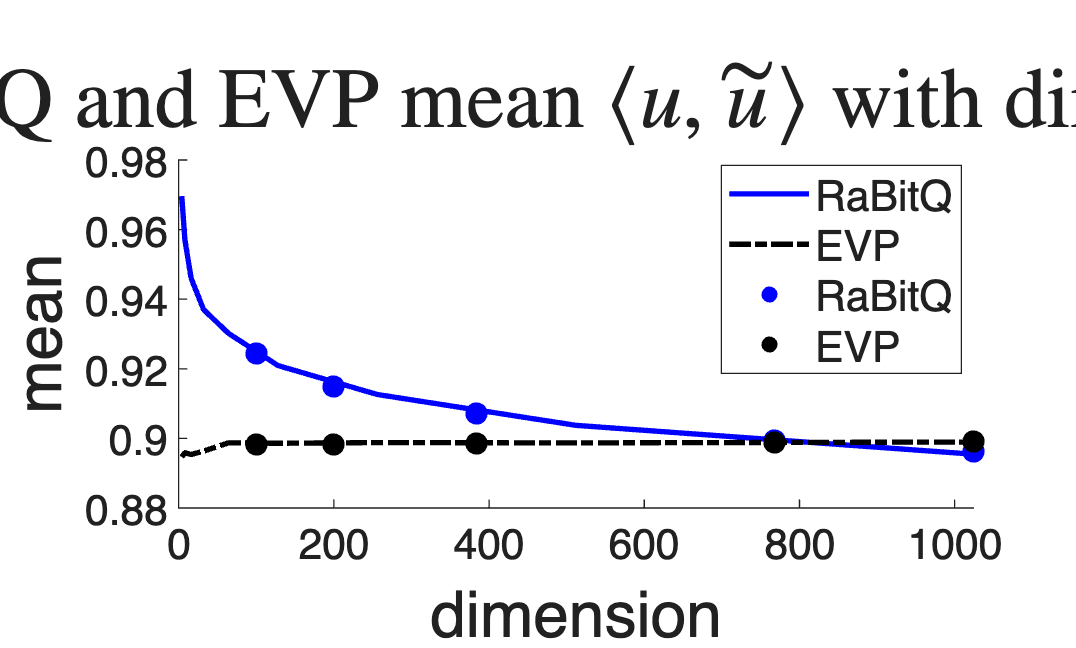


figure;
ax=gca;
ax.FontSize=16;
xlim([0,1024]);
xlabel("dimension",FontSize=24)
ylabel("mean",FontSize=24)
hold on;
title("RaBitQ and EVP mean $\langle u,\tilde{u} \rangle$ with dimension",'Interpreter','latex',FontSize=32)
plot(dims,errors(1,:),LineWidth=2,Color="blue",LineStyle="-");
plot(dims,errors(2,:),LineWidth=2,Color="black",LineStyle="-.");
scatter(realdims,errorsReal(1,:),70,"blue","filled");
scatter(realdims,errorsReal(2,:),70,"black","filled");
legend("RaBitQ","EVP","RaBitQ","EVP",location="best",FontSize=16);
hold off;

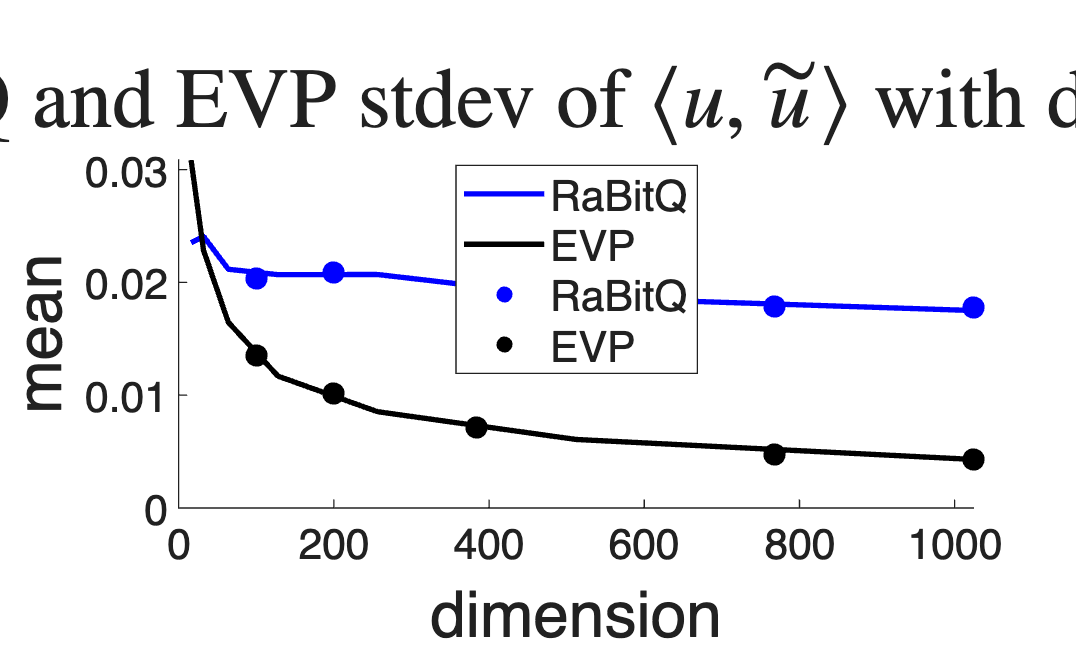


figure;
ax=gca;
ax.FontSize=16;
xlim([0,1024]);
xlabel("dimension",FontSize=24)
ylabel("mean",FontSize=24)
hold on;
title("RaBitQ and EVP stdev of $\langle u,\tilde{u} \rangle$ with dimension",'Interpreter','latex',FontSize=32)
plot(dims(3:end),errorStDev(1,3:end) ./ errors(1,3:end),LineWidth=2,Color="blue",LineStyle="-");
plot(dims(3:end),errorStDev(2,3:end) ./ errors(1,3:end),LineWidth=2,Color="black",LineStyle="-");
scatter(realdims,errorStDevReal(1,:) ./ errorsReal(1,:),70,"blue","filled");
scatter(realdims,errorStDevReal(2,:) ./ errorsReal(2,:),70,"black","filled");
legend("RaBitQ","EVP","RaBitQ","EVP",location="best",FontSize=16);
hold off;

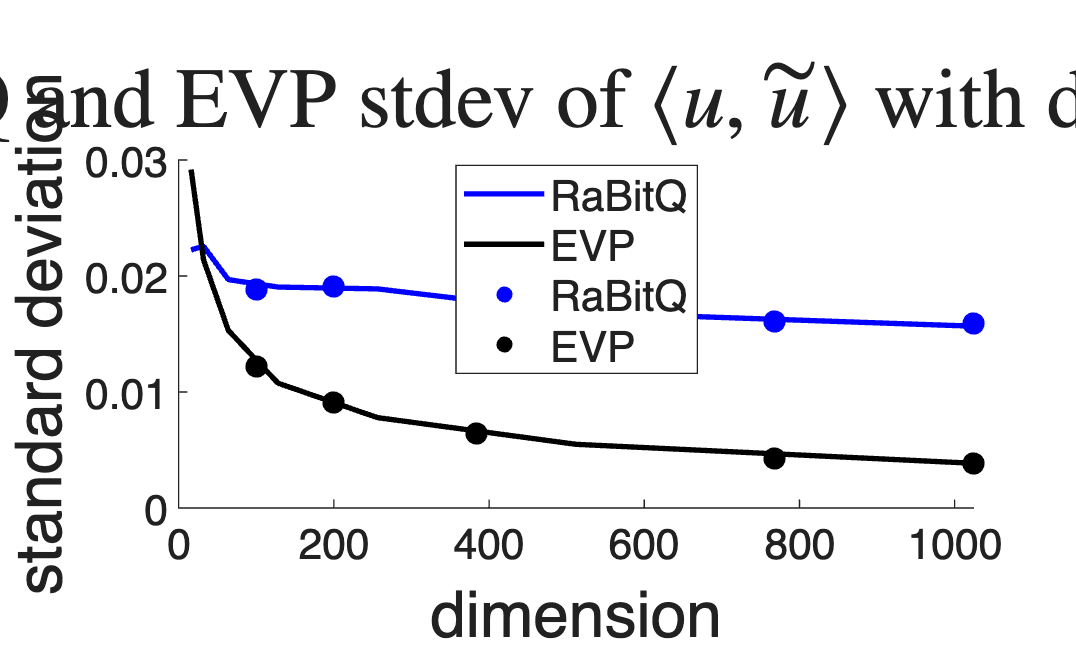


figure;
ax=gca;
ax.FontSize=16;
xlim([0,1024]);
xlabel("dimension",FontSize=24)
ylabel("standard deviation",FontSize=24)
hold on;
title("RaBitQ and EVP stdev of $\langle u,\tilde{u} \rangle$ with dimension",'Interpreter','latex',FontSize=32)
plot(dims(3:end),errorStDev(1,3:end),LineWidth=2,Color="blue",LineStyle="-");
plot(dims(3:end),errorStDev(2,3:end),LineWidth=2,Color="black",LineStyle="-");
scatter(realdims,errorStDevReal(1,:),70,"blue","filled");
scatter(realdims,errorStDevReal(2,:),70,"black","filled");
legend("RaBitQ","EVP","RaBitQ","EVP",location="best",FontSize=16);
hold off;

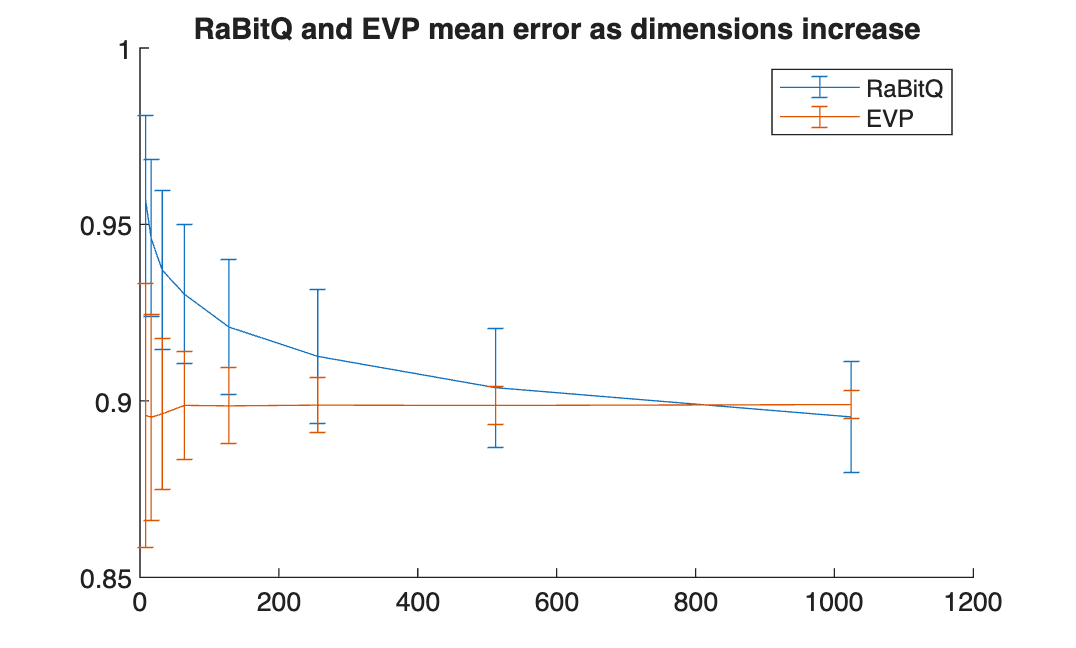


figure;
hold on;
title("RaBitQ and EVP mean error as dimensions increase")
errorbar(dims(2:end),errors(1,2:end),errorStDev(1,2:end));
errorbar(dims(2:end),errors(2,2:end),errorStDev(2,2:end));
legend("RaBitQ","EVP");
hold off;